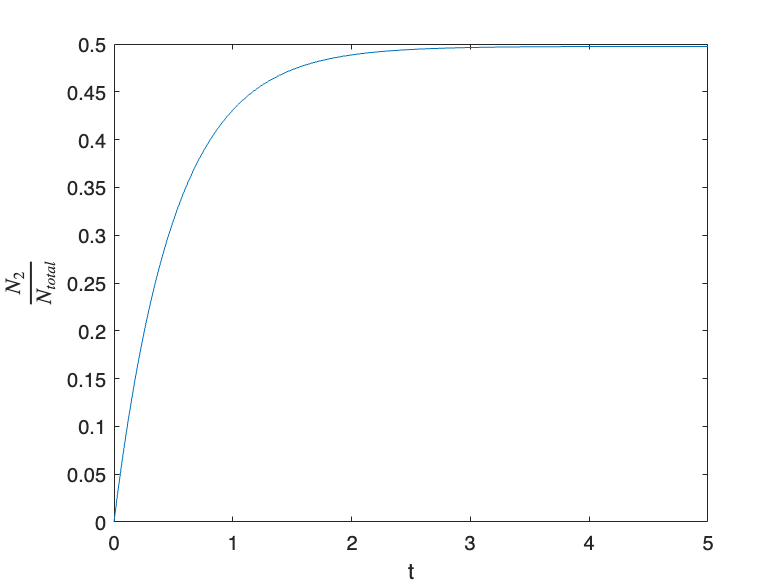

%simulating excited state population over time (N2/Ntotal)

%stimulated term (B*rho)
B_rho = 1;
%spontaneous emission rate
A = 0.01;

%time array from 0 to 5, step size = 0.01
t = 0:0.01:5;

%analytical solution for N2/Ntotal over time
N2_Ntotal = B_rho./(2*B_rho+A).*(1-exp(-(2*B_rho+A).*t));

%plotting
figure;
plot(t, N2_Ntotal);
box on
xlabel('t');
ylabel('$\frac{N_2}{N_{total}}$','Interpreter','latex')